# Matlab for Signals and systems - Exam 08/2022

In the file Signal.mat, we provide the vector y and the vector t which correspond to the signal to analyze. This signal consists of several components: 

- A continuous component of amplitude 75

- A fundamental wave at 20Hz

- Harmonics of rank 2, 3 and 20. 

You are asked to: 

**1)** Visualize the sampled signal as a function of time (as a sample). Then determine the frequency (Fs) and the sampling period (Ts).

clear all; close all
load ("signal.mat")

% code


**2) **Apply the FFT on the time signal and display its frequency content (Amp and f).

% code


Explain and justify the necessity of the different operations applied to represent this frequency content. Do not hesitate to use schematic if necessary. 

**Expected result :**

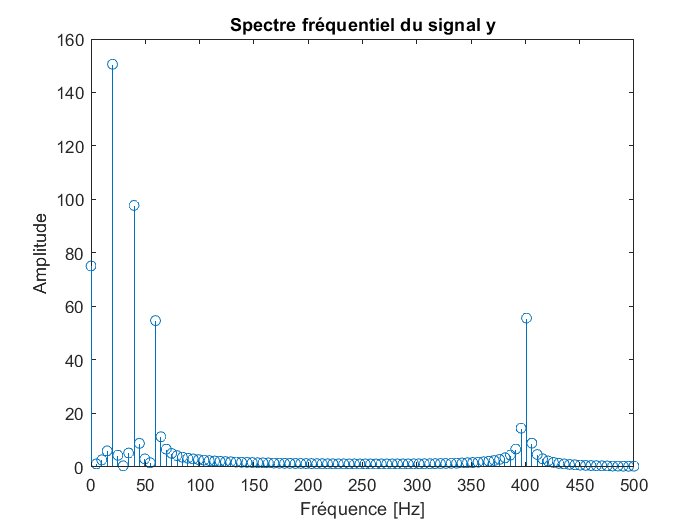

Explain the problem(s) encountered on the frequency spectrum. Which phenomenon(s) are involved? Justify with diagrams and explanations. 

**3) **Correct the problem(s) encountered and display the frequency content obtained. 

% code
t_f=1/20;
N1=round(t_f/ts);
y1=y(1:N1);
t1=t(1:N1);
stem(t1,y1)

n=length(y1);
x=abs(fft(y1))/n;
x=x(1:n/2+1);
x=x*2
x(1)=x(1)/2;

df=fs/n;
N=0:1:n/2;
f=N*df;
stem(f,x)

**Expected result :**

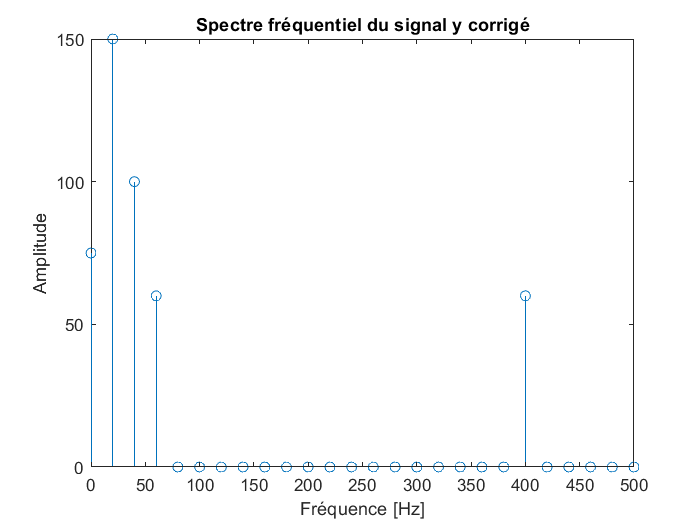

**4) **Create a transfer function of the system H. 

The transfer function is the following : $H\left(s\right)=\frac{1\;}{\frac{s²}{{\omega_c }^2 \;}\;+\frac{2s\xi }{\omega_c \;\;}+1}$ with $\omega_c$= 574 rad/s and $\xi$ = 0.65. 

Find the response time at 99% of the system. 

% code
wc=574;
clear tf
ksi=0.65;
s=tf('s');
h=1/((s^2/wc^2)+(2*s*ksi/wc)+1)

pole(h);
T=-1/max(real(pole(h)))
Tss=5*T

**5) **Apply, at the input of the system, the original signal y. Then apply the FFT on the output signal of the system obtained (yf1) **in steady state**. 

If you are unable to recover the yf1 signal (in steady state) by yourself, you can use the one available in the .mat file.

% code
yf=lsim(h,y,t)
plot(t,y,t,yf)


index=min(find(t>Tss)); %#ok<MXFND>
yf1=yf(index*5:index*5+N1-1);
tf1=t(index*5:index*5+N1-1);
length(yf1);

stem(tf1,yf1);
n=length(yf1);
Xf=abs(fft(yf1))/n;
Xf=Xf(1:n/2+1);
Xf=Xf*2
Xf(1)=Xf(1)/2;

df=fs/n;
N=0:1:n/2;
f=N*df;
stem(f,Xf)



Then compare (by superimposing them on the same graph) the frequency spectrum of the input signal (Amp) with the frequency spectrum of the output signal (Amp2). Visualize the whole for a frequency going from 0 to 500 Hz.

% code
hold on 
stem(f,x)
legend('Signal de sortie', "signal d'entrée")

**Expected result :**

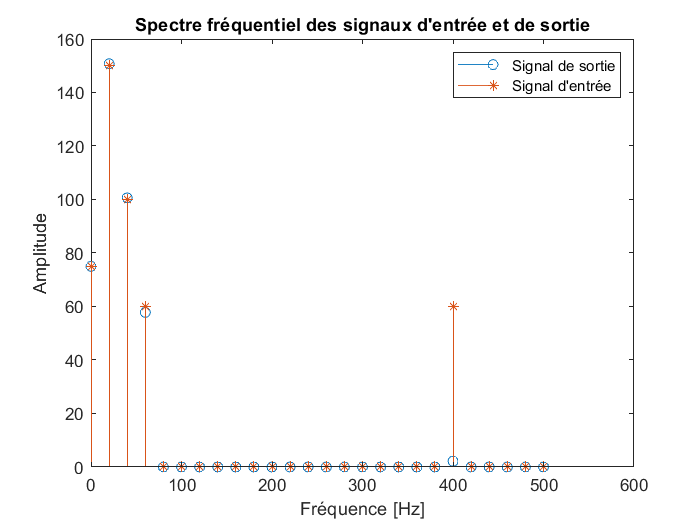

**6)** Compare the temporal signal at the output of the filter in steady state (yf1) with the one reconstructed from the frequency analysis (to be stored in y_r).

NB: The original time signal was constructed with sines. 

% code
Xf;
y_r=Xf(1)+Xf(2)*sin(2*pi*f(2)*tf1)+Xf(3)*sin(2*pi*f(3)*tf1)+Xf(4)*sin(2*pi*f(4)*tf1)+Xf(21)*sin(2*pi*f(21)*tf1)
figure
plot(tf1,y_r,tf1,yf1)
legend('Signal reconstruit','Signal Yf1')

**Expected result :**

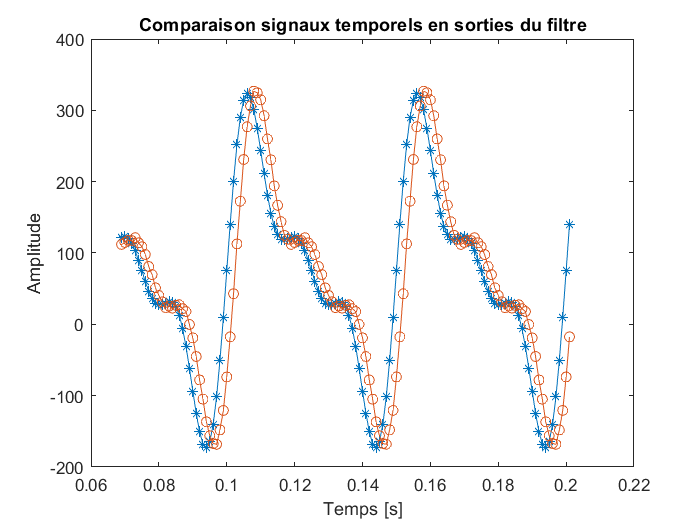

Justify the shift observed between the yf1 signal and the one reconstructed via frequency analysis.